# Example for using the `interprgb` function.

Copyright © 2021 Tamas Kis

We want to draw 5 squares in a row, where the first square is blue, the fifth square is red, and where the three squares in between are gradually interpolated from blue to red.

First, we define the colors of the 1st (blue) and 5th (red) squares.

c1 = [0,0,1];
c5 = [1,0,0];

Interpolating for the colors of the three intermediate squares,

% square #2: 75% blue, 25% red
c2 = interprgb(c1,c5,0.25);

% square #3: 50% blue, 50% red
c3 = interprgb(c1,c5,0.5);

% square #4: 25% blue, 75% red
c4 = interprgb(c1,c5,0.75);

Drawing the five squares,

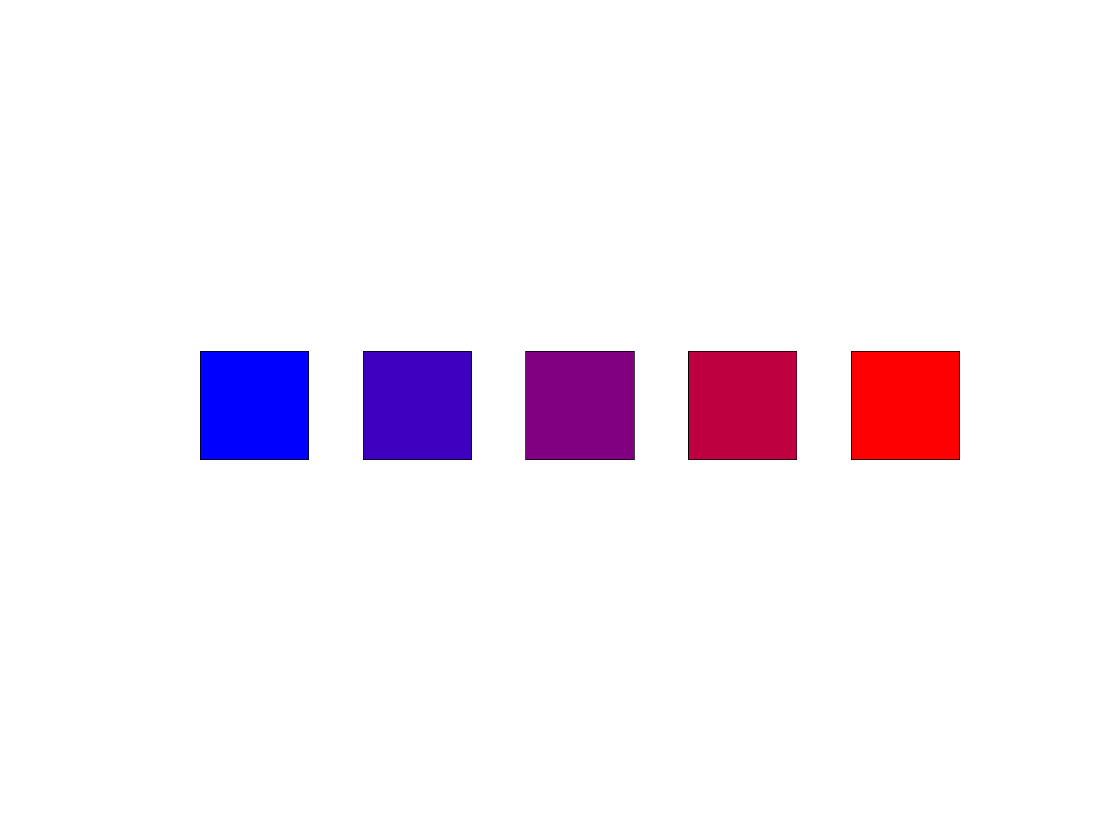

figure;
hold on;
rectangle('Position',[1,1,2,2],'facecolor',c1);
rectangle('Position',[4,1,2,2],'facecolor',c2);
rectangle('Position',[7,1,2,2],'facecolor',c3);
rectangle('Position',[10,1,2,2],'facecolor',c4);
rectangle('Position',[13,1,2,2],'facecolor',c5);
axis equal;
xlim([0,16]);
ylim([0,4]);
axis off;
hold off;